# Deformaciones Residuales Según la TCL

## Constantes ingenieriles:

CI=[
152.878	9.962	0.401	3.703	3.703	4.427	0.401	0.125
137.510	9.755	0.373	3.638	3.638	3.730	0.373	0.308
133.207	8.354	0.383	3.128	3.128	3.560	0.383	0.173
129.146	8.180	0.377	3.066	3.066	3.417	0.377	0.197
167.057	11.793	0.412	4.350	4.350	5.306	0.412	0.111
148.733	9.235	0.401	3.442	3.442	4.214	0.401	0.096
134.732	10.556	0.360	3.931	3.931	3.627	0.360	0.455
160.257	10.859	0.407	4.022	4.022	4.850	0.407	0.120
139.632	9.171	0.384	3.423	3.423	3.811	0.384	0.203
162.559	11.918	0.403	4.399	4.399	5.001	0.403	0.192
    ];
E1=CI(:,1);
E2=CI(:,2);
NU_12=CI(:,3);
G_12=CI(:,4);
G_13=CI(:,5);
G_23=CI(:,6);
NU_13=CI(:,7);
NU_23=CI(:,8);

## Constantes Q:

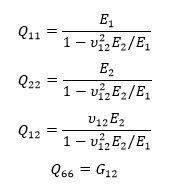

Q11 = zeros(10);
Q22 = zeros(10);
Q12 = zeros(10);
Q66 = zeros(10);
for i = 1:1:10
    Q11(i) = E1(i) / (1 - (NU_12(i)^2) * (E2(i) / E1(i))); % GPa
    Q22(i) = E2(i) / (1 - (NU_12(i)^2) * (E2(i) / E1(i))); % GPa
    Q12(i) = (NU_12(i) * E2(i)) / (1 - (NU_12(i)^2) * (E2(i) / E1(i))); % GPa
    Q66(i) = G_12(i); % GPa
end
clear i;

## Ángulos de Cada Corrida

Matriz_corridas=[
    89 -89 45 -45 05 -05 -45 45 -89 89 0 0 0 0 0 0 0 0 0 0
    89 -89 45 -45 05 -05 -45 45 -89 89 0 0 0 0 0 0 0 0 0 0
    45 -45 45 -45 45 -45 -45 45 -45 45 0 0 0 0 0 0 0 0 0 0
    45 -45 45 -45 45 -45 -45 45 -45 45 0 0 0 0 0 0 0 0 0 0
    45 -45 45 -45 45 -45 -45 45 -45 45 0 0 0 0 0 0 0 0 0 0
    45 -45 45 -45 45 -45 -45 45 -45 45 0 0 0 0 0 0 0 0 0 0
    89 89 -89 -89 45 45 -45 -45 05 -05 -05 05 -45 -45 45 45 -89 -89 89 89
    89 89 -89 -89 45 45 -45 -45 05 -05 -05 05 -45 -45 45 45 -89 -89 89 89
    89 89 -89 -89 05 05 -05 -05 89 -89 -89 89 -05 -05 05 05 -89 -89 89 89
    89 89 -89 -89 05 05 -05 -05 89 -89 -89 89 -05 -05 05 05 -89 -89 89 89
    ];

## Matriz de espesores

Matriz_espesores=[
        1.75
        1.52
        1.7
        1.84
        1.52
        1.39
        2.99
        2.65
        2.66
        3.4
   ];

## Volumenes de fibra, resina y poros:

fracciones_en_volumen=[
    3.383	63.387	33.229
    9.000	56.956	34.044
    5.009	55.075	39.916
    5.828	53.366	40.806
    2.769	69.386	27.846
    2.442	61.617	35.942
    12.777	55.833	31.415
    3.124	66.510	30.366
    5.935	57.811	36.254
    4.920	67.511	27.569
    ];
V_f=fracciones_en_volumen(:,1);
V_m=fracciones_en_volumen(:,2);
V_p=fracciones_en_volumen(:,3);

## Alfas de capa unidireccional

## 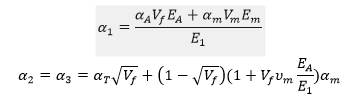

alfa_a = -0.00000038; % 1/ºC
alfa_t = 0.0000095; % 1/ºC
alfa_m = 0.0000576; % 1/ºC
E_a = 239.400; % GPa
E_m = 3.400; % GPa
NU_m = 0.31;
alfa_1=zeros(10);
alfa_2=zeros(10);
for i = 1:1:10
    alfa_1(i) = (alfa_a * V_f(i) * E_a + alfa_m * V_f(i) * E_m)/E1(i);
    alfa_2(i) = alfa_t * (V_f(i)^0.5) + (1 - (V_f(i)^0.5))*(1 + V_f(i) * NU_m * (E_a / E1(i))) * alfa_m;
end 
clear i;

## Constantes Φ

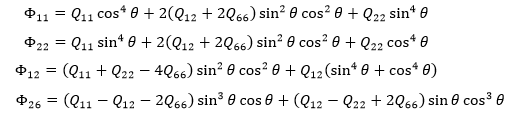

% t = angulo expresado en radianes
% PHI_11k = q11 * (cos(t)^4) + 2 * (q12 + 2 * q66) * (sin(t)^2) * (cos(t)^2) + q22 * (sin(t)^4);
% PHI_22k = q11 * (sin(t)^4) + 2 * (q12 + 2 * q66) * (sin(t)^2) * (cos(t)^2) + q22 * (cos(t)^4);
% PHI_12k = (q11 + q22 - 4 * q66) * (sin(t)^2) * (cos(t)^2) + q12 * ((sin(t)^4) + (cos(t)^4));
% PHI_26k = (q11 - q12 - 2 * q66) * (sin(t)^3) * (cos(t)) + (q12 - q22 + 2 * q66) * (sin(t)) * (cos(t)^3);

## Calcular A₂₂

% tk = espesor de la capa k
% A22 = 0;
% N = cantidad de capas
% for i = 1:1:N
%     PHI_22k = q11 * (sin(t)^4) + 2 * (q12 + 2 * q66) * (sin(t)^2) * (cos(t)^2) + q22 * (cos(t)^4);
%     A22 = PHI_22k * tk +A22
% end

## Constantes de capa orientada αx, αy, αxy

% alfa_x = alfa_1 * (cos(t)^2) + alfa_2 * (sin(t)^2);
% alfa_y = alfa_1 * (sin(t)^2) + alfa_2 * (cos(t)^2);
% alfa_xy = 2 * (cos(t)) * (sin(t)) * (alfa_1 - alfa_2);

## Deformaciones Residuales según la TCL:

epsilon_y_0 = zeros(10);
A22 = zeros(10);
sumatoria = zeros(10);
t_k = zeros(10);
Ni = zeros(10);
for i = 1:1:10
    q11 = Q11(i);
    q12 = Q12(i);
    q66 = Q66(i);
    q22 = Q22(i);
    e = Matriz_espesores(i); % espesor total de la corrida i
    a1 = alfa_1(i);
    a2 = alfa_2(i);
    A22(i)=0;
    sumatoria(i)=0;
    if i < 7
      N = 10;
    else
      N = 20;
    end
    t_k(i) = e / N;
    Ni(i) = N;
    for j = 1:1:N
        tk = t_k(i);  % espesor de la capa
        t = deg2rad(Matriz_corridas(i,j)); % angulo de la capa expresado en radianes
        PHI_22k = q11 * (sin(t)^4) + 2 * (q12 + 2 * q66) * (sin(t)^2) * (cos(t)^2) + q22 * (cos(t)^4);
        PHI_12k = (q11 + q22 - 4 * q66) * (sin(t)^2) * (cos(t)^2) + q12 * ((sin(t)^4) + (cos(t)^4));
        PHI_26k = (q11 - q12 - 2 * q66) * (sin(t)^3) * (cos(t)) + (q12 - q22 + 2 * q66) * (sin(t)) * (cos(t)^3);
        alfa_x = a1 * (cos(t)^2) + a2 * (sin(t)^2);
        alfa_y = a1 * (sin(t)^2) + a2 * (cos(t)^2);
        alfa_xy = 2 * (cos(t)) * (sin(t)) * (a1 - a2);
        A22(i) = A22(i) + PHI_22k * tk;
        sumatoria(i) = sumatoria(i) + (PHI_12k * alfa_x + PHI_22k * alfa_y + PHI_26k * alfa_xy) * tk;
    end
    clear j;
    epsilon_y_0(i) = -44 * sumatoria(i) / A22(i);
end
clear i;